# Train Multiple Environments

clear all;
close all;

## 環境の宣言

T1 = 1;
K1 = 1;
F = 1;
[A, B, C, D] = tf2ss([K1], [T1 1]);
sys = ss(A,B,C,D);
sysd1 = c2d(sys, 0.01);

T2 = 2;
K2 = 0.5;
[A, B, C, D] = tf2ss([K2], [T2 1]);
sys = ss(A,B,C,D);
sysd2 = c2d(sys, 0.01);

C1 = [C -1];

x0 = [0; 1];

### 報酬関数の設計

Q = 1000;
R = 1;

Q1 = C1'*Q*C1;

### 環境のインスタンス

subEnv1 = rlDiscreteLQTEnv(sysd1.A, sysd1.B, sysd1.C, F, Q, R,'x0', x0);
subEnv2 = rlDiscreteLQTEnv(sysd2.A, sysd2.B, sysd2.C, F, Q, R);
env = rlMultipleEnvironment({subEnv1, subEnv2});
rng(0)

## エージェントのインスタンス

### エージェントオプションの作成

K0 = [0.3 1.3 0.75];
moduleAgentOpts = rlLQTAgentOptions('StepNumPerIteration', 20, 'DiscountFactor', 0.8, 'SaveExperiences', true);
agentOpts = rlAdaptiveModularAgentOptions("Vigilance", 1e-5, "SaveExperiences", true);

### ノイズモデルの生成

moduleAgentOpts.NoiseOptions.Mean = 0;
moduleAgentOpts.NoiseOptions.Variance = 2;

### エージェントのインスタンス

createModuleFcn = @() createLQTAgentModule(getObservationInfo(env), getActionInfo(env), moduleAgentOpts);
agent = rlAdaptiveModularAgent(createModuleFcn, agentOpts);

## エージェントの学習

trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',1, ...
    'MaxStepsPerEpisode',1500, ...
    'StopTrainingValue', 100000, ...
    'Verbose',true, ...
    'Plots','none');

trainingStats = train(agent, env, trainingOpts);

Episode:   1/  1 | Episode Reward : -29137.19 | Episode Steps: 1500 | Avg Reward : -29137.19 | Step Count : 1500


## 実験結果のプロット

experience = getExperiences(agent);

observation     = cellfun(@(x)x{1},experience,'UniformOutput',false);
action          = cellfun(@(x)x{2},experience,'UniformOutput',false);
reward          = cellfun(@(x)x{3},experience,'UniformOutput',false);
nextobservation = cellfun(@(x)x{4},experience,'UniformOutput',false);
isdone          = cellfun(@(x)x{5},experience,'UniformOutput',false);
selectedModuleID = getBuffer(agent.SelectedModuleID);

### 報酬のプロット

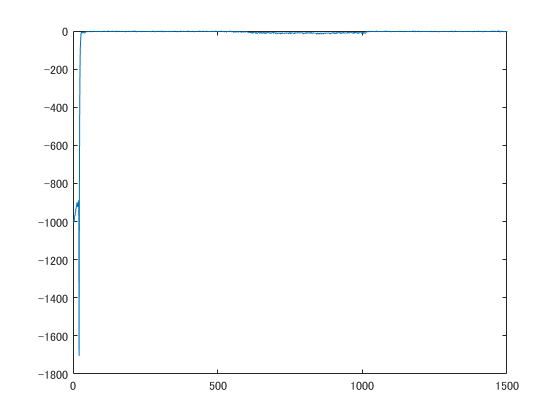

plot(cell2mat(reward));

## 選択されたモジュールのプロット

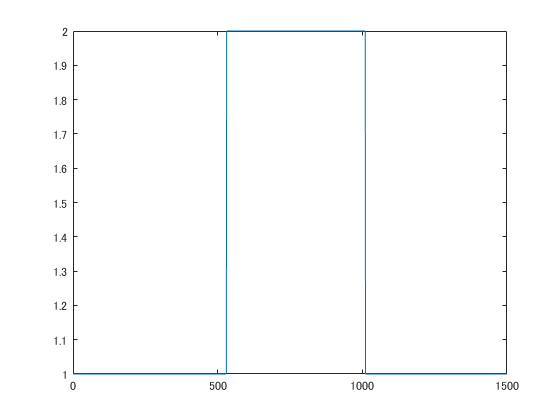

plot(cell2mat(selectedModuleID))